# Análise de AM

clear all;
close all;
clc;

## Sinal modulado  - resposta temporal

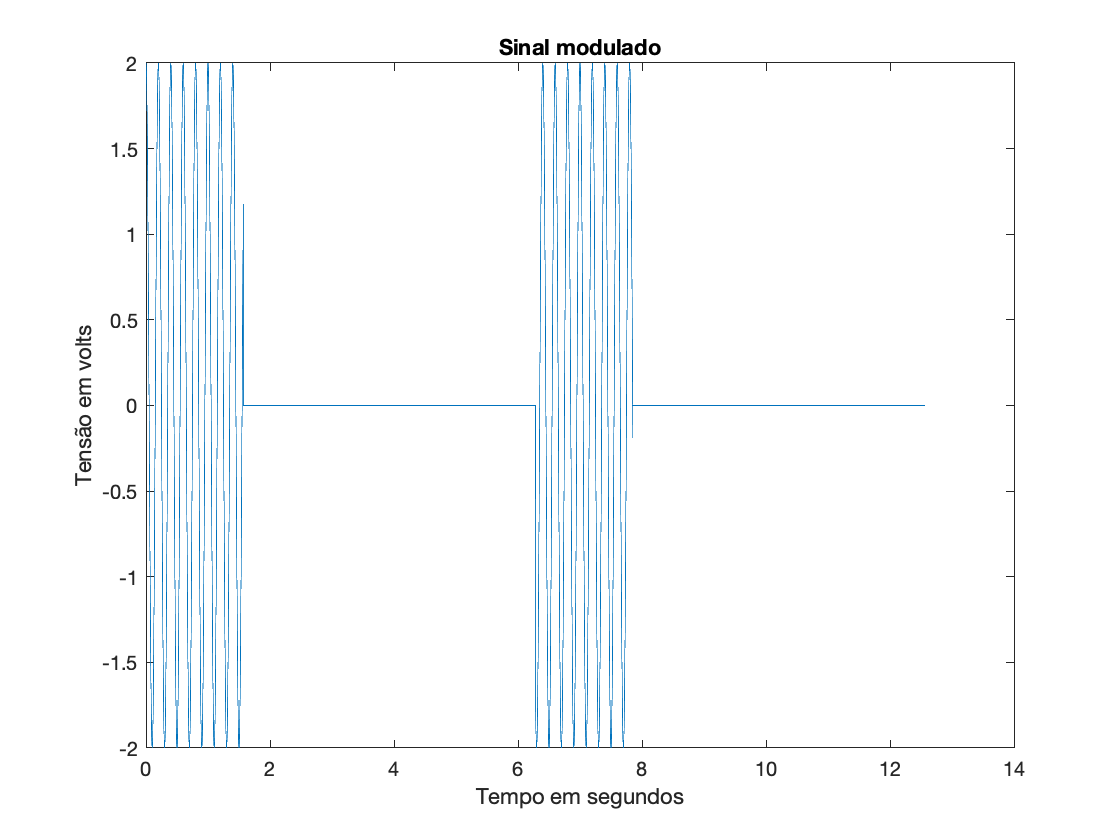

Ts    = 1e-3;               % resolução
tempo = [0:Ts:4*pi];        % vetor tempo

m = 1;

switch m
        case {1}
            
        %%% Tempo
        
        Ec = 1;
        wc = 10*pi;
        m = square(tempo,25);
        AM = [m + Ec].*cos(wc*tempo);
        
        figure()
        plot(tempo,AM);
        xlabel('Tempo em segundos')
        ylabel('Tensão em volts')
        title('Sinal modulado')
        saveas(gcf,'AM01T.png')       
        
        case {2}
        Ec = 1;
        wc = 10*pi;
        m = square(tempo,75);
        AM = [m + Ec].*cos(wc*tempo);
        
        figure()
        plot(tempo,AM);
        xlabel('Tempo em segundos')
        ylabel('Tensão em volts')
        title('Sinal modulado')
        saveas(gcf,'AM02T.png')
        
        case {3}
        Ec = 2;
        wc = 20*pi;
        m = square(tempo,33.3);
        AM = [m + Ec].*cos(wc*tempo);
        
        figure()
        plot(tempo,AM);
        xlabel('Tempo em segundos')
        ylabel('Tensão em volts')
        title('Sinal modulado')
        saveas(gcf,'AM03T.png')
        
        case {4}
        Ec = 1.5;
        wc = 20*pi;
        m = square(tempo,66.6);
        AM = [m + Ec].*cos(wc*tempo);
        
        figure()
        plot(tempo,AM);
        xlabel('Tempo em segundos')
        ylabel('Tensão em volts')
        title('Sinal modulado')
        saveas(gcf,'AM04T.png')
end

## Sinal modulado - Resposta em frequência

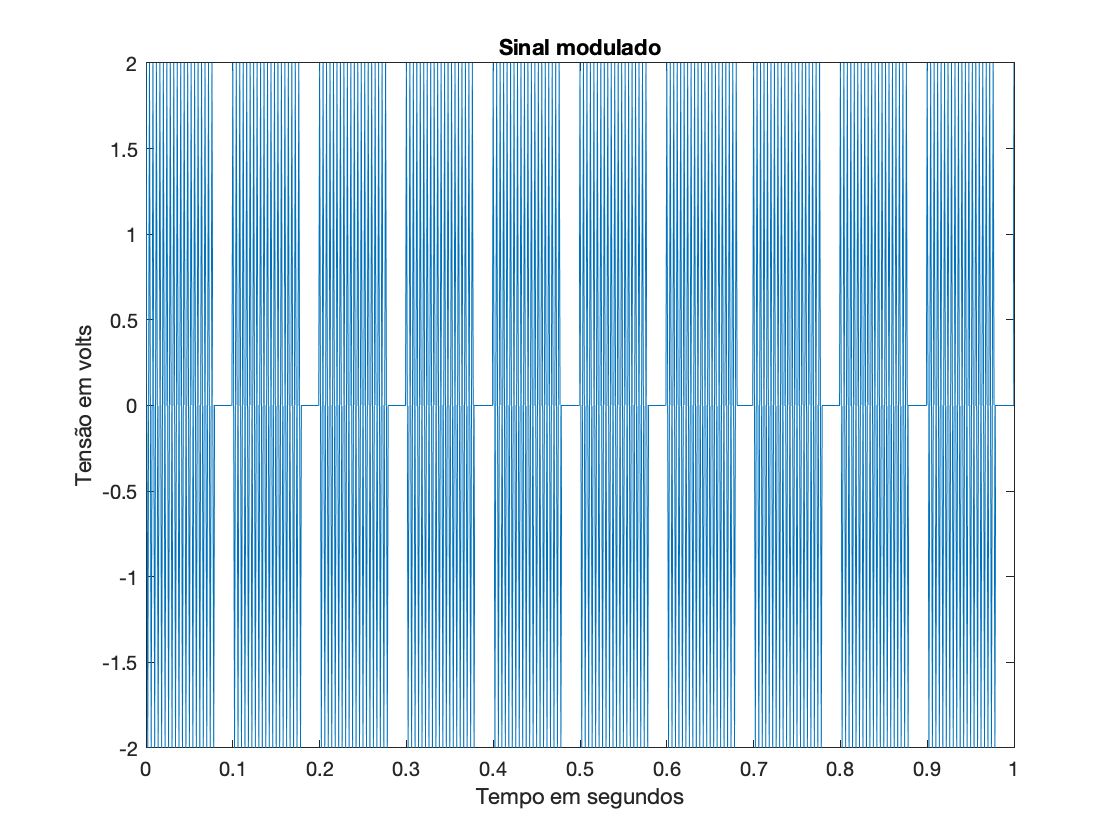

freq =   -500  -499  -498  -497  -496  -495  -494  -493  -492  -491  -490  -489  -488  -487  -486  -485  -484  -483  -482  -481  -480  -479  -478  -477  -476  -475  -474  -473  -472  -471  -470  -469  -468  -467  -466  -465  -464  -463  -462  -461  -460  -459  -458  -457  -456  -455  -454  -453  -452  -451


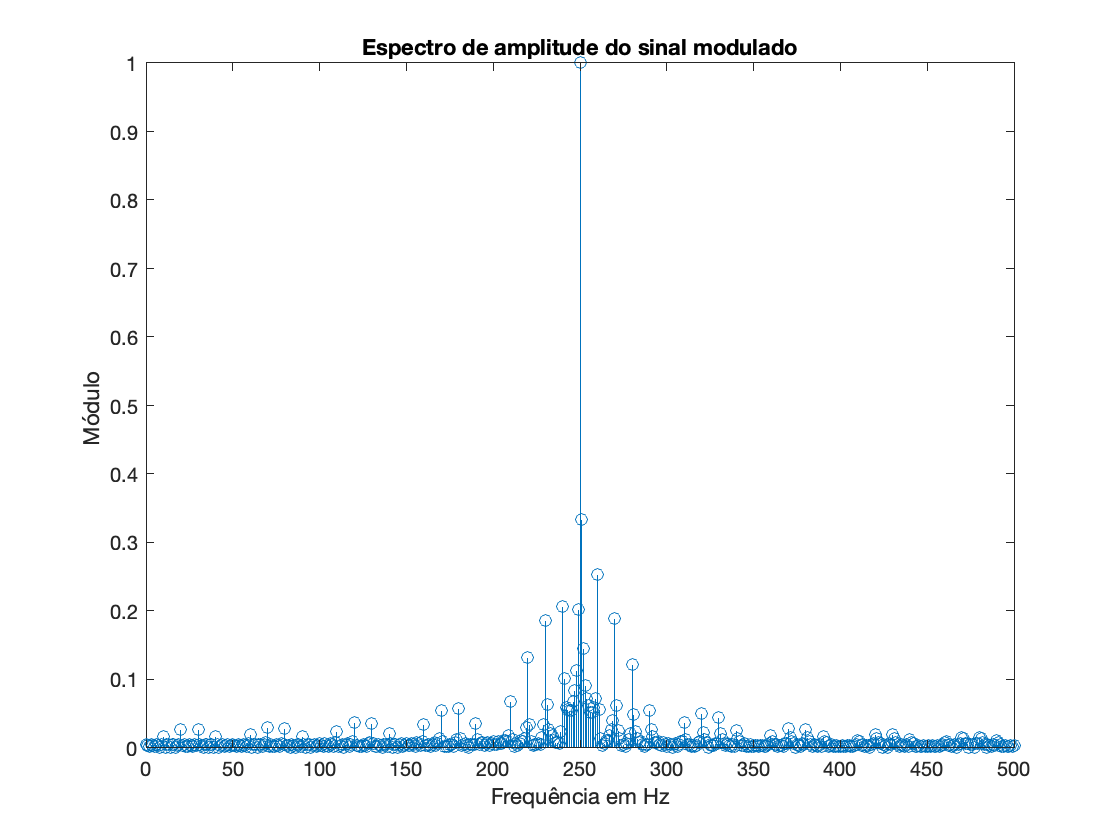

Ts    = 1e-3;               % resolução
tempo = [0:Ts:1];        % vetor tempo

m = 4;

switch m
        case {1}
            
        %%% Tempo
        
        Ec = 1.0;
        wc = 500*pi;
        wm = 5;
        m = square(2*pi*wm*tempo,10);
        AM = [m + Ec].*cos(wc*tempo);
        
        figure()
        plot(tempo,AM);
        xlabel('Tempo em segundos')
        ylabel('Tensão em volts')
        title('Sinal modulado')
        
        %%% Frequência
        freq = linspace(-0.5/Ts,0.5/Ts,length(tempo))
        AMmod = fftshift(abs(fft(AM)));
        
        figure()
        
        stem(freq,AMmod/max(AMmod));
        xlabel('Frequência em Hz')
        ylabel('Módulo ')
        title('Espectro de amplitude do sinal modulado')

        xlim([0 500])
        ylim([0.000 1])
        saveas(gcf,'AM01F.png')
      
        case {2}
        
        Ec = 1.0;
        wc = 500*pi;
        wm = 10;
        m = square(2*pi*wm*tempo,25);
        AM = [m + Ec].*cos(wc*tempo);
        
        figure()
        plot(tempo,AM);
        xlabel('Tempo em segundos')
        ylabel('Tensão em volts')
        title('Sinal modulado')
        
        %%% Frequência
        freq = linspace(-0.5/Ts,0.5/Ts,length(tempo))
        AMmod = fftshift(abs(fft(AM)));
        
        figure()
        
        stem(freq,AMmod/max(AMmod));
        xlabel('Frequência em Hz')
        ylabel('Módulo ')
        title('Espectro de amplitude do sinal modulado')

        xlim([0 500])
        ylim([0.000 1])
        
        saveas(gcf,'AM02F.png')
        
        case {3}
        
        Ec = 1.0;
        wc = 500*pi;
        wm = 5;
        m = square(2*pi*wm*tempo,20);
        AM = [m + Ec].*cos(wc*tempo);
        
        figure()
        plot(tempo,AM);
        xlabel('Tempo em segundos')
        ylabel('Tensão em volts')
        title('Sinal modulado')
        
        %%% Frequência
        freq = linspace(-0.5/Ts,0.5/Ts,length(tempo))
        AMmod = fftshift(abs(fft(AM)));
        
        figure()
        
        stem(freq,AMmod/max(AMmod));
        xlabel('Frequência em Hz')
        ylabel('Módulo ')
        title('Espectro de amplitude do sinal modulado')

        xlim([0 500])
        ylim([0.000 1])
        
        saveas(gcf,'AM03F.png')
        
        case {4}
        
        Ec = 1.0;
        wc = 500*pi;
        wm = 10;
        m = square(2*pi*wm*tempo,80);
        AM = [m + Ec].*cos(wc*tempo);
        
        figure()
        plot(tempo,AM);
        xlabel('Tempo em segundos')
        ylabel('Tensão em volts')
        title('Sinal modulado')
        
        %%% Frequência
        freq = linspace(-0.5/Ts,0.5/Ts,length(tempo))
        AMmod = fftshift(abs(fft(AM)));
        
        figure()
        
        stem(freq,AMmod/max(AMmod));
        xlabel('Frequência em Hz')
        ylabel('Módulo ')
        title('Espectro de amplitude do sinal modulado')

        xlim([0 500])
        ylim([0.000 1])
        
        saveas(gcf,'AM04F.png')
end